%页码：P86
%作者；暴富
%时间：2024-07-9
%项目：复数多项式判稳

clc
clear

% 定义矩阵 A 和 B
A = [-2, -1; 2, 1];
B = [1; 0];

% 定义向量 K
% K = [0.5, 0.5];
K = [1.544 1.8901];


% 定义符号变量 s,复数 sigma
syms s x y;
iota = sqrt(-1);
sigma = x + iota * y;

% 计算矩阵 A - sigma * B * K
A_sigma_BK = A - sigma * (B * K);

% A_sigma_BK = A -  (B * K);

% 计算矩阵 sI - (A - sigma * B * K)
I = eye(size(A));
matrix = s * I - A_sigma_BK;

% 计算行列式
determinant = det(matrix);

% 显示结果
disp('The determinant of sI - (A - sigma * B * K) is:');

The determinant of sI - (A - sigma * B * K) is:


disp(determinant);

$$s+\frac{11181\,x}{5000}+\frac{193\,s\,x}{125}+s^{2}+\frac{11181\,y\,\mathrm{i}}{5000}+\frac{193\,s\,y\,\mathrm{i}}{125}$$

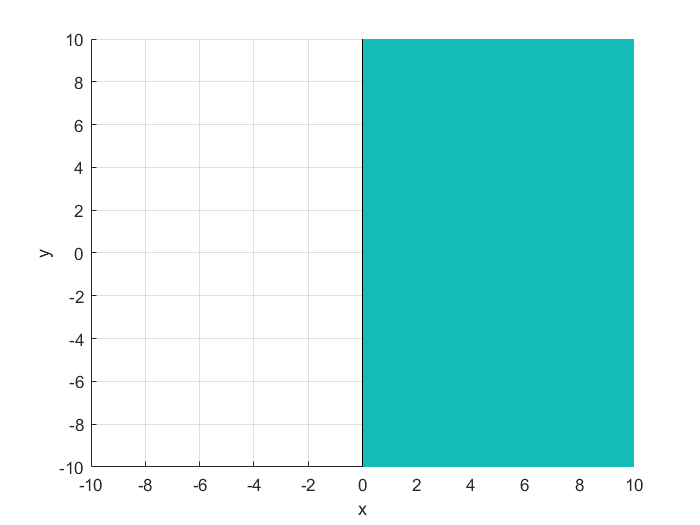

% 定义不等式函数
% f = @(x, y) (x / 2) .* (1 - x / 2).^2 - (1 - x / 8) .* y.^2;
f = @(x, y) (x .* y.^2) / 8 + (x.^3) / 8 + (x.^2) / 2 + x / 2;
% 创建一个网格范围
x = linspace(-10, 10, 1000);
y = linspace(-10, 10, 1000);
[X, Y] = meshgrid(x, y);

% 计算不等式函数值
Z = f(X, Y);

% 绘制不等式区域
figure;
hold on;
contourf(X, Y, Z, [0, Inf], 'LineStyle', 'none'); % 填充满足不等式的区域
fimplicit(@(x, y) f(x, y) - eps, [-10 10 -10 10], 'k'); % 绘制不等式边界

% 设置图形标题和坐标轴标签
%title('Region where \frac{x}{2}\left(1-\frac{x}{2}\right)^{2}-\left(1-\frac{x}{8}\right)y^{2}>0');
xlabel('x');
ylabel('y');

% 设置网格
grid on;
% colorbar; % 显示颜色条
hold off;

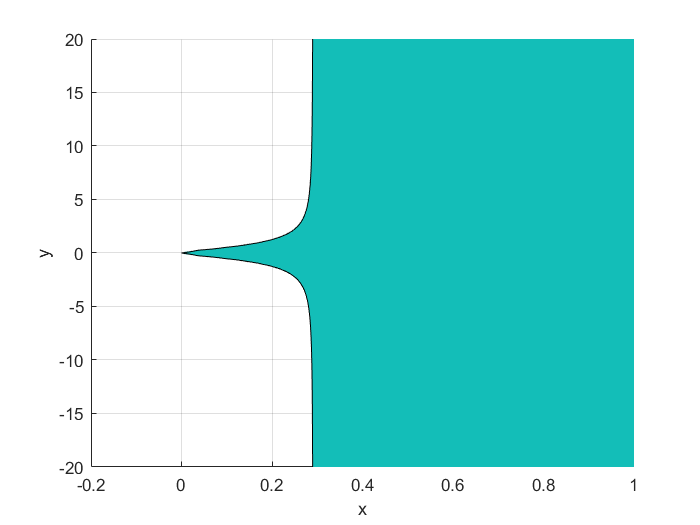

% 定义不等式函数
% f = @(x, y) (x .* y.^2) / 8 + (x.^3) / 8 + (x.^2) / 2 + x / 2;
% f = @(x, y) (-3.*y.^2.*(1-x)+3.*x.*(1-x).^2-9.*y.^2);
f = @(x, y) ((1.544.*x+1).*1.544.*y.*2.2362.*y+(1.544.*x+1).^2.*2.2362.*x-(2.2362.*y).^2);

% 创建一个网格范围
x = linspace(-0.2, 1, 1000);
y = linspace(-20, 20, 1000);
[X, Y] = meshgrid(x, y);

% 计算不等式函数值
Z = f(X, Y);

% 绘制不等式区域
figure;
hold on;
contourf(X, Y, Z, [0, Inf], 'LineStyle', 'none'); % 填充满足不等式的区域
fimplicit(@(x, y) f(x, y) - eps, [-0.2 1 -20 20], 'k'); % 绘制不等式边界

% 设置图形标题和坐标轴标签
%title('\frac{xy^2}{8}+\frac{x^3}{8}+\frac{x^2}{4}+\frac{x}{2}>0');
xlabel('x');
ylabel('y');

% 设置网格
grid on;
% colorbar; % 显示颜色条
hold off;